#### Plot Supplementary Figure 7a, simulating zero-width (delta) pulse and finite-width pulse, without flip angle error

figure()
subplot(1,3,1)

load N=10_ave=50_DeltaPulse_varyTau_Ratio.mat
load N=10_ave=50_DeltaPulse_varyTau_std_Ratio.mat
mean_Ratio1=mean_Ratio;
std_Ratio1=std_Ratio;

load N=10_ave=50_FinitePulse_ns=4_varyTau_Ratio.mat
load N=10_ave=50_FinitePulse_ns=4_varyTau_std_Ratio.mat
mean_Ratio2=mean_Ratio;
std_Ratio2=std_Ratio;


color={"#FF0000"
    "#0072BD"
    "#D95319"
    "#00FF00"
    "#EDB120"
    "#0000FF"
    "#7E2F8E"
    "#00FFFF"
    "#77AC30"
    "#FF00FF"
    "#4DBEEE"
    "#000000"
    "#A2142F"
    };


x1=1:0.2:6;
x2=2.4:0.2:6;
errorbar(x1,mean_Ratio1(:),std_Ratio1(:),'o','markerfacecolor',color{1},'color',color{1},'markersize',3,'capsize',0)
hold on 

errorbar(x2,mean_Ratio2(:),std_Ratio2(:),'s','markerfacecolor',color{2},'color',color{2},'markersize',3,'capsize',0)

plot([0 6],[1.5,1.5],':b','linewidth',1)

legend('$\delta$-shape pulse','$\tau_p=2$ $\mu$s pulse','interpreter','latex','box','off')

xlabel('Average pulse interval $\tau$ ($\mu$s)','Interpreter','latex')

ylabel('$I_2^{(x)}/I_0^{(x)}$','Interpreter','latex')
ylim([1.4 1.7])
xticks(0:0.5:6)
xticklabels({'0','','1','','2','','3','','4','','5','','6'})
xtickangle(0)

#### Plot Supplementary Figure 7b, simulating effects of flip angle errors, for finite pulse case

load N=10_ave=50_FinitePulse_ns=4_varyTau_Ratio.mat
load N=10_ave=50_FinitePulse_ns=4_varyTau_std_Ratio.mat
mean_Ratio2=mean_Ratio;
std_Ratio2=std_Ratio;

load N=10_ave=50_FlipError=-0.01_FinitePulse_ns=2_J1460Hz_varyTau_Ratio
load N=10_ave=50_FlipError=-0.01_FinitePulse_ns=2_J1460Hz_varyTau_std_Ratio
mean_Ratio3=mean_Ratio;
std_Ratio3=std_Ratio;

load N=10_ave=50_FlipError=0.01_FinitePulse_ns=2_J1460Hz_varyTau_Ratio
load N=10_ave=50_FlipError=0.01_FinitePulse_ns=2_J1460Hz_varyTau_std_Ratio
mean_Ratio4=mean_Ratio;
std_Ratio4=std_Ratio;

load N=10_ave=50_FlipError=0.02_FinitePulse_ns=2_J1460Hz_varyTau_Ratio
load N=10_ave=50_FlipError=0.02_FinitePulse_ns=2_J1460Hz_varyTau_std_Ratio
mean_Ratio5=mean_Ratio;
std_Ratio5=std_Ratio;

color={"#FF0000"
    "#0072BD"
    "#D95319"
    "#00FF00"
    "#EDB120"
    "#0000FF"
    "#7E2F8E"
    "#00FFFF"
    "#77AC30"
    "#FF00FF"
    "#4DBEEE"
    "#000000"
    "#A2142F"
    };

subplot(1,3,2)
x3=2.4:0.2:6;
x2=2.4:0.2:6;
errorbar(x3,mean_Ratio3(:),std_Ratio3(:),'^','markerfacecolor',color{3},'color',color{3},'markersize',4,'capsize',0)
hold on 
errorbar(x2,mean_Ratio2(:),std_Ratio2(:),'s','markerfacecolor',color{2},'color',color{2},'markersize',5,'capsize',0)
errorbar(x3,mean_Ratio4(:),std_Ratio4(:),'o','color',color{4},'markersize',4,'capsize',1)
errorbar(x3,mean_Ratio5(:),std_Ratio5(:),'x','color',color{5},'markersize',5,'capsize',1)

plot([0 6],[1.5,1.5],':b','linewidth',1)

legend('$\eta=-0.01$','$\eta=0$','$\eta=0.01$','$\eta=0.02$','interpreter','latex','box','off')

xlabel('Average pulse interval $\tau$ ($\mu$s)','Interpreter','latex')
% xlabel('$t_{\mathrm{dip}}$ ($\mu$s)','Interpreter','latex')

ylabel('$I_2^{(x)}/I_0^{(x)}$','Interpreter','latex')
ylim([0.6 1.8])
xlim([2,6])
xticks(2:0.5:6)
xticklabels({'2','','3','','4','','5','','6','','7'})
% fontsize(gcf,10,'points')
% fontname(gcf,"Times")
% set(gcf,'unit','centimeters','position',[10,10,16,6]);


#### Plot Supplementary Figure 7c, showing experimental results on how the flip angle errors effect the MQC ratio, by varying the RF pulse power

load Exp_plw1=108wto117w_xi=-0.1_-0.1_0.2_ns=4_tauTimesLoop=200_Ratio.mat
load Exp_plw1=108wto117w_xi=-0.1_-0.1_0.2_ns=4_tauTimesLoop=200_Ratio_std.mat

color={"#FF0000"
    "#0072BD"
    "#D95319"
    "#00FF00"
    "#EDB120"
    "#0000FF"
    "#7E2F8E"
    "#00FFFF"
    "#77AC30"
    "#FF00FF"
    "#4DBEEE"
    "#000000"
    "#A2142F"
    };
marker={'^','s','o','x'}

marker = 1×4 cell 数组
    {'^'}    {'s'}    {'o'}    {'x'}



tau=2.4:0.2:6;
x=tau;
plw1=roundn(113*(0.98:0.01:1.02).^2,-2)

plw1 =   108.5300  110.7500  113.0000  115.2700  117.5700


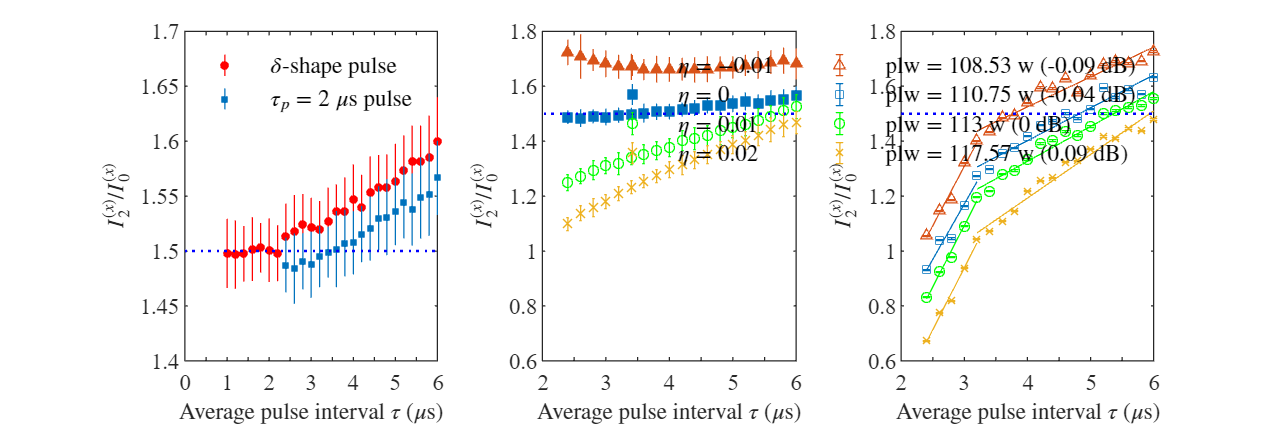


subplot(1,3,3)
ii=1;
index=[3,2,4,5];

for i=[2,3,1,5]
error_bar=1.96*Ratio_std((i-1)*length(tau)+1:i*length(tau));
y=Ratio((i-1)*length(tau)+1:i*length(tau));

p1=polyfit(x(1:5),y(1:5),1);
p2=polyfit(x(5:end),y(5:end),1);

errorbar(x,y,error_bar,marker{ii},'color',color{index(ii)},'MarkerSize',4,'CapSize',3)
hold on
xx=linspace(x(1),x(5),10);
plot(xx,polyval(p1,xx),'color',color{index(ii)})
xx=linspace(x(5),x(end),10);
plot(xx,polyval(p2,xx),'color',color{index(ii)})

ii=ii+1;
end
plot([2,6],[1.5,1.5],'b:','linewidth',1)
xlabel('Average pulse interval $\tau$ ($\mu$s)','Interpreter','latex')
ylabel('$I_2^{(x)}/I_0^{(x)}$','Interpreter','latex')

xticks(2:0.5:6)
xticklabels({'2','','3','','4','','5','','6','','7'})

ylim([0.6 1.8])
legend('plw$=108.53$ w (-0.09 dB)','','','plw$=110.75$ w (-0.04 dB)','','','plw$=113$ w (0 dB)','','','plw$=117.57$ w (0.09 dB)','','','interpreter','latex','box','off')

% xlim([4 6])
% ylim([1.3 1.6])
fontsize(gcf,9,'points')
fontname(gcf,"Times New Roman")
set(gcf,'unit','centimeters','position',[10,10,18,6]);
xtickangle(0)